# Lab 7 - Working with Image

## 0. Plot a Vector in Matlab

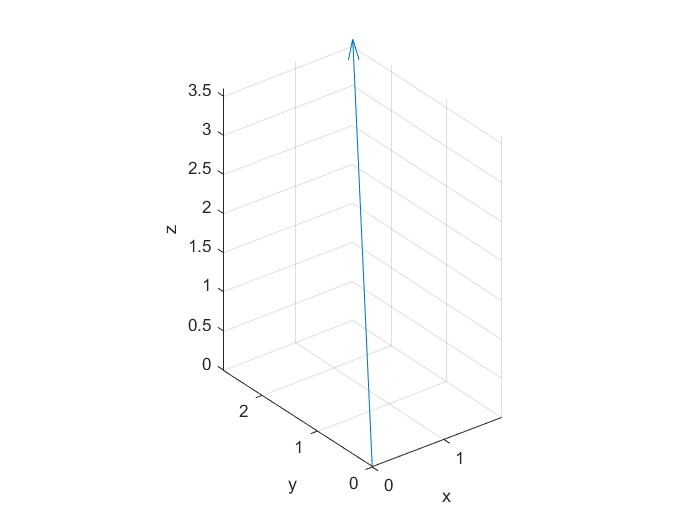

quiver3(0,0,0,2,3,4);
%how to plot a vector a = (2,3,4) for this lab
axis equal
xlabel('x')
ylabel('y')
zlabel('z') %labels for the vector

## 1. Projection

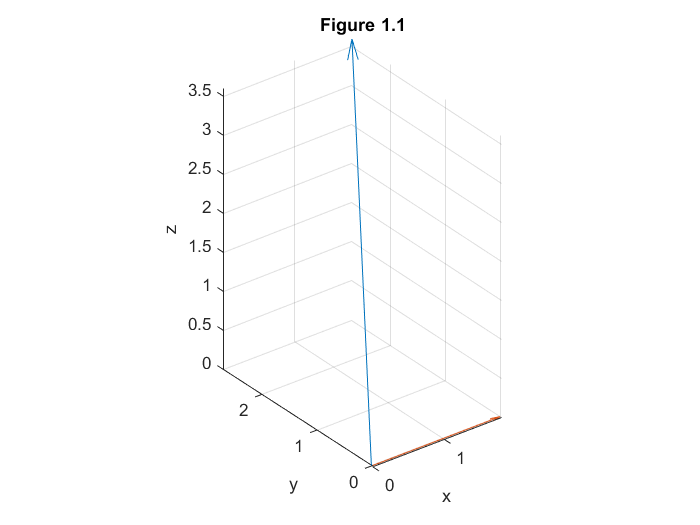

figure
quiver3(0,0,0,2,3,4) %plot a
hold on
quiver3(0,0,0,2,0,0) %plot Px of a
title('Figure 1.1')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold off

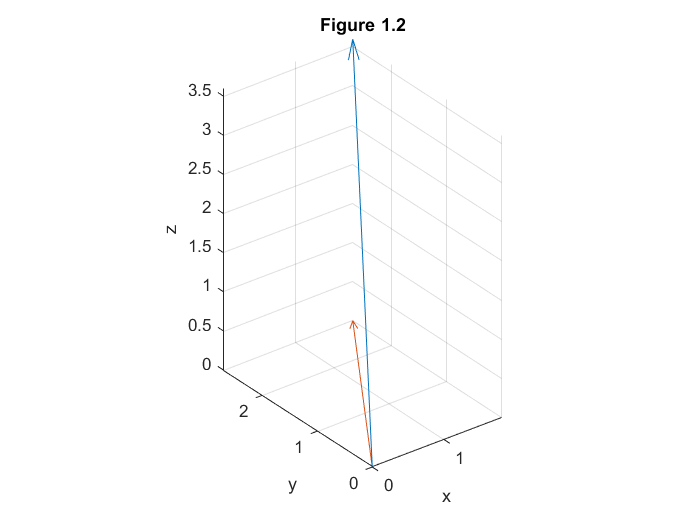


figure
quiver3(0,0,0,2,3,4) %plot a
hold on
quiver3(0,0,0,2,3,0) %plot Pxy of a
title('Figure 1.2')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold off

## 2. Rotation Matrix

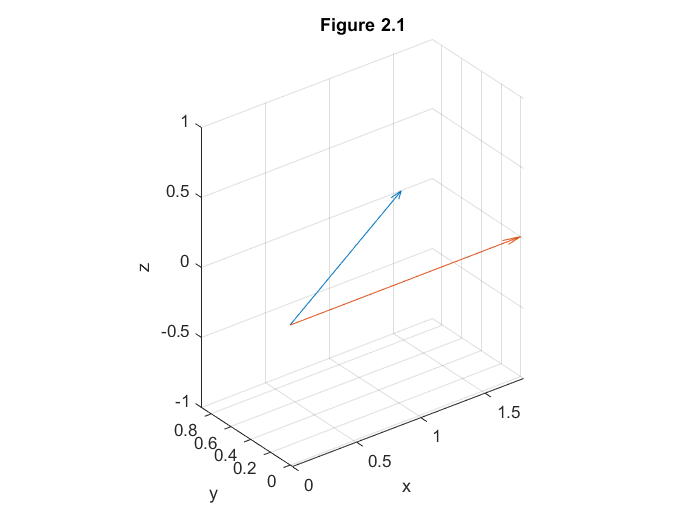

Rz = [cosd(30) -sind(30) 0; sind(30) cosd(30) 0; 0 0 1];
%rotation matrix around z-axis at a degree of 30
Px = [2; 0; 0];
PxRotz = Rz*Px;
%getting the value of Px after using the rotation matrix
figure
quiver3(0,0,0,PxRotz(1), PxRotz(2), PxRotz(3))
%plot rotated vector
hold on
quiver3(0,0,0, Px(1),Px(2),Px(3))
%plot original vector
title('Figure 2.1')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold off

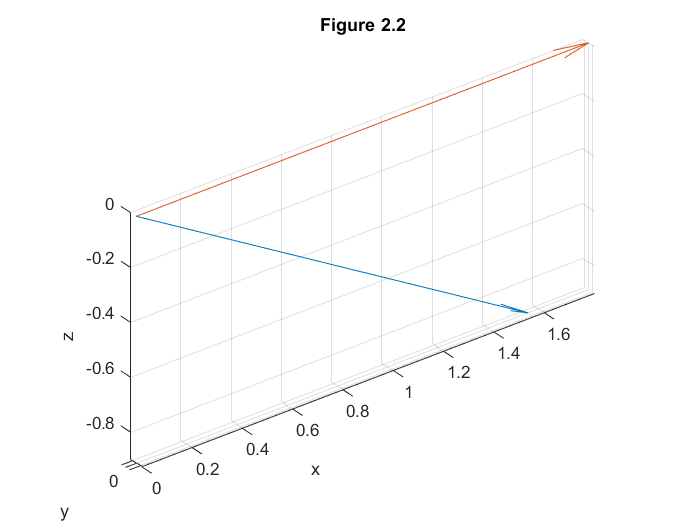



Ry = [cosd(30) 0 sind(30); 0 1 0; -sind(30) 0 cosd(30)];
%rotation matrix around z-axis at a degree of 30
Px = [2;0;0];
PxRoty = Ry*Px;
%getting the value of Px after using the rotation matrix
figure
quiver3(0,0,0,PxRoty(1), PxRoty(2), PxRoty(3))
%plot rotated vector
hold on
quiver3(0,0,0, Px(1),Px(2),Px(3))
%plot original vector
title('Figure 2.2')
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold off

## 3. Image Compression by SVD

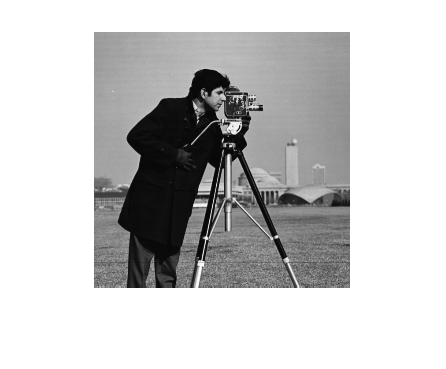

raw = imread('cameraman.tif'); %load the cameraman image
figure
imshow(raw);

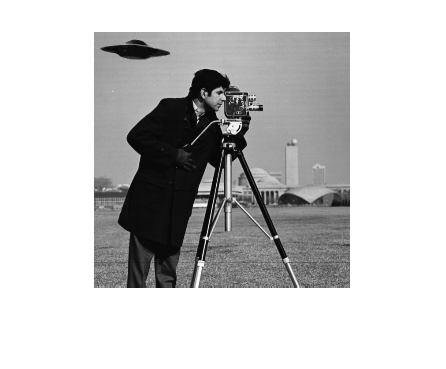


UFO = imread('UFO.png'); %load UFO image
% Next few lines remove UFO image background
% and move it to the corner of the cameraman image
UFO1 = 255-UFO;
raw(1:36,1:81)=raw(1:36,1:81)+UFO1;
raw(1:36,1:81)=raw(1:36,1:81)-UFO1;
figure
imshow(raw) % show the new image with the UFO

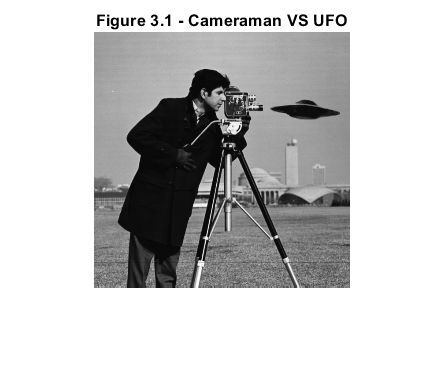


raw = imread('cameraman.tif'); %reload cameraman image
UFO1 = 255-UFO;
x=60; %values to move UFO from corner to in front of camera
y=170;
raw(1+x:36+x,1+y:81+y)=raw(1+x:36+x,1+y:81+y)+UFO1;
raw(1+x:36+x,1+y:81+y)=raw(1+x:36+x,1+y:81+y)-UFO1;
figure
imshow(raw) % show the new image with the UFO
title('Figure 3.1 - Cameraman VS UFO')

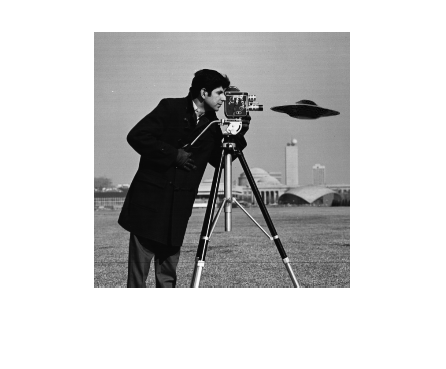


A=single(raw); %compressing image with functions
I=uint8(A);
imshow(I);


[U,S,V] = svd(A); %compressing image with svd function
A_new=U*S*V';
I_new=uint8(A_new);
imshow(I_new);

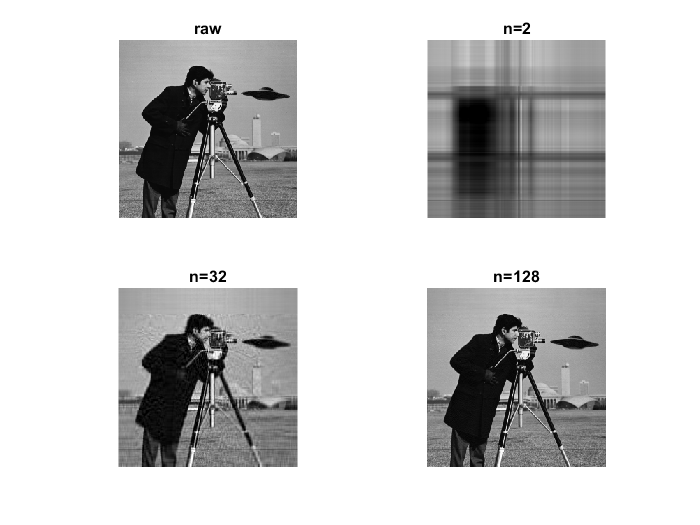


figure %plotting compressed versions of the image
subplot(2,2,1)
imshow(raw);
title('raw')
S2=[S(:,1:2) zeros(256, 256-2)]; 
A_2=U*S2*V';
I_2 = uint8(A_2);
subplot(2,2,2)
imshow(I_2)
title('n=2')
S32=[S(:,1:32) zeros(256, 256-32)];
A_32=U*S32*V';
I_32 = uint8(A_32);
subplot(2,2,3)
imshow(I_32)
title('n=32')
S128=[S(:,1:128) zeros(256, 256-128)];
A_128=U*S128*V';
I_128 = uint8(A_128);
subplot(2,2,4)
imshow(I_128)
title('n=128')